ground_target_data = ["Austin", 30.2672, -97.7431, 15;
               "New York", 40.7128, -74.0060, 10;
               "Los Angeles", 34.0522, -118.4837, 71;
               "Chicago", 41.8781, -87.6298, 181;
               "Houston", 29.7604, -95.3698, 30;
               "Phoenix", 33.4484, -112.0740, 331;
               "Philadelphia", 39.9526, -75.1652, 12;
               "San Antonio", 29.4481, -98.4936, 198;
               "San Diego", 32.7157, -117.1611, 22;
               "Dallas", 32.7767, -96.7970, 137;
               "London", 51.5074, -0.1278, 35;
               "Tokyo", 35.6895, 139.6917, 6;
               "Paris", 48.8566, 2.3522, 35;
               "Moscow", 55.7558, 37.6176, 155;
               "Sydney", -33.8688, 151.2093, 19;
               "Toronto", 43.6511, -79.3830, 76;
               "Berlin", 52.5200, 13.4050, 34;
               "Rome", 41.9028, 12.4964, 17;
               "Seoul", 37.5665, 126.9780, 23;
               "Mumbai", 19.0760, 72.8777, 14;
               "Beijing", 39.9042, 116.4074, 43;
               "Mexico City", 19.4326, -99.1332, 2240;
               "São Paulo", -23.5505, -46.6333, 780;
               "Bangkok", 13.7563, 100.5018, 2;
               "Istanbul", 41.0082, 28.9784, 39;
               "Cairo", 30.0444, 31.2357, 23;
               "Dubai", 25.2769, 55.2963, 4;
               "Singapore", 1.3521, 103.8198, 15;
               "Hong Kong", 22.3193, 114.1694, 39;
               "Sydney", -33.8688, 151.2093, 19];



ground_station_data = ["Svalbard, Norway", 78.2300, 15.4100, 120;
                 "Alaska Satellite Facility, USA", 64.8581, -147.8494, 133;
                 "King Sejong Station, Antarctica", -62.2233, -58.7855, 11;
                 "Troll Station, Antarctica", -72.0167, 2.5333, 1275;
                 "McMurdo Station, Antarctica", -77.8419, 166.6863, 24;
                 "Tromsø, Norway", 69.6492, 18.9560, 10;
                 "Inuvik, Canada", 68.3600, -133.7236, 65;
                 "Prince Albert, Canada", 53.2022, -105.7453, 428;
                 "Wallops Island, Virginia, USA", 37.9402, -75.4661, 14;
                 "Santiago, Chile", -33.4489, -70.6693, 520;
                 "Hartebeesthoek, South Africa", -25.8870, 27.7044, 1415;
                 "Dongara, Australia", -29.2049, 114.9389, 20];

ground_station_data_4GS = ["Svalbard, Norway", 78.2300, 15.4100, 120;
                 "Alaska Satellite Facility, USA", 64.8581, -147.8494, 133;
                 "Hartebeesthoek, South Africa", -25.8870, 27.7044, 1415;
                 "Dongara, Australia", -29.2049, 114.9389, 20];


figure;
g = geoaxes;
hold(g, 'on')

% Define ground target coordinates and labels
ground_target = str2double(ground_target_data(:,2:3))

ground_target =    30.2672  -97.7431
   40.7128  -74.0060
   34.0522 -118.4837
   41.8781  -87.6298
   29.7604  -95.3698
   33.4484 -112.0740
   39.9526  -75.1652
   29.4481  -98.4936
   32.7157 -117.1611
   32.7767  -96.7970


ground_target_labels = ground_target_data(:,1)

ground_target_labels = 30×1 string 배열
    "Austin"
    "New York"
    "Los Angeles"
    "Chicago"
    "Houston"
    "Phoenix"
    "Philadelphia"
    "San Antonio"
    "San Diego"
    "Dallas"
    "London"
    "Tokyo"
    "Paris"
    "Moscow"
    "Sydney"
    "Toronto"
    "Berlin"
    "Rome"
    "Seoul"
    "Mumbai"
    "Beijing"
    "Mexico City"
    "São Paulo"
    "Bangkok"
    "Istanbul"
    "Cairo"
    "Dubai"
    "Singapore"
    "Hong Kong"
    "Sydney"




% Define ground station coordinates and labels
ground_station = str2double(ground_station_data(:,2:3))

ground_station =    78.2300   15.4100
   64.8581 -147.8494
  -62.2233  -58.7855
  -72.0167    2.5333
  -77.8419  166.6863
   69.6492   18.9560
   68.3600 -133.7236
   53.2022 -105.7453
   37.9402  -75.4661
  -33.4489  -70.6693


ground_station_labels = ground_station_data(:,1)

ground_station_labels = 12×1 string 배열
    "Svalbard, Norway"
    "Alaska Satellite Facility, USA"
    "King Sejong Station, Antarctica"
    "Troll Station, Antarctica"
    "McMurdo Station, Antarctica"
    "Tromsø, Norway"
    "Inuvik, Canada"
    "Prince Albert, Canada"
    "Wallops Island, Virginia, USA"
    "Santiago, Chile"
    "Hartebeesthoek, South Africa"
    "Dongara, Australia"




% Define ground station coordinates and labels
ground_station_4GS = str2double(ground_station_data_4GS(:,2:3))

ground_station_4GS =    78.2300   15.4100
   64.8581 -147.8494
  -25.8870   27.7044
  -29.2049  114.9389


ground_station_4GS_labels = ground_station_data_4GS(:,1)

ground_station_4GS_labels = 4×1 string 배열
    "Svalbard, Norway"
    "Alaska Satellite Facility, USA"
    "Hartebeesthoek, South Africa"
    "Dongara, Australia"


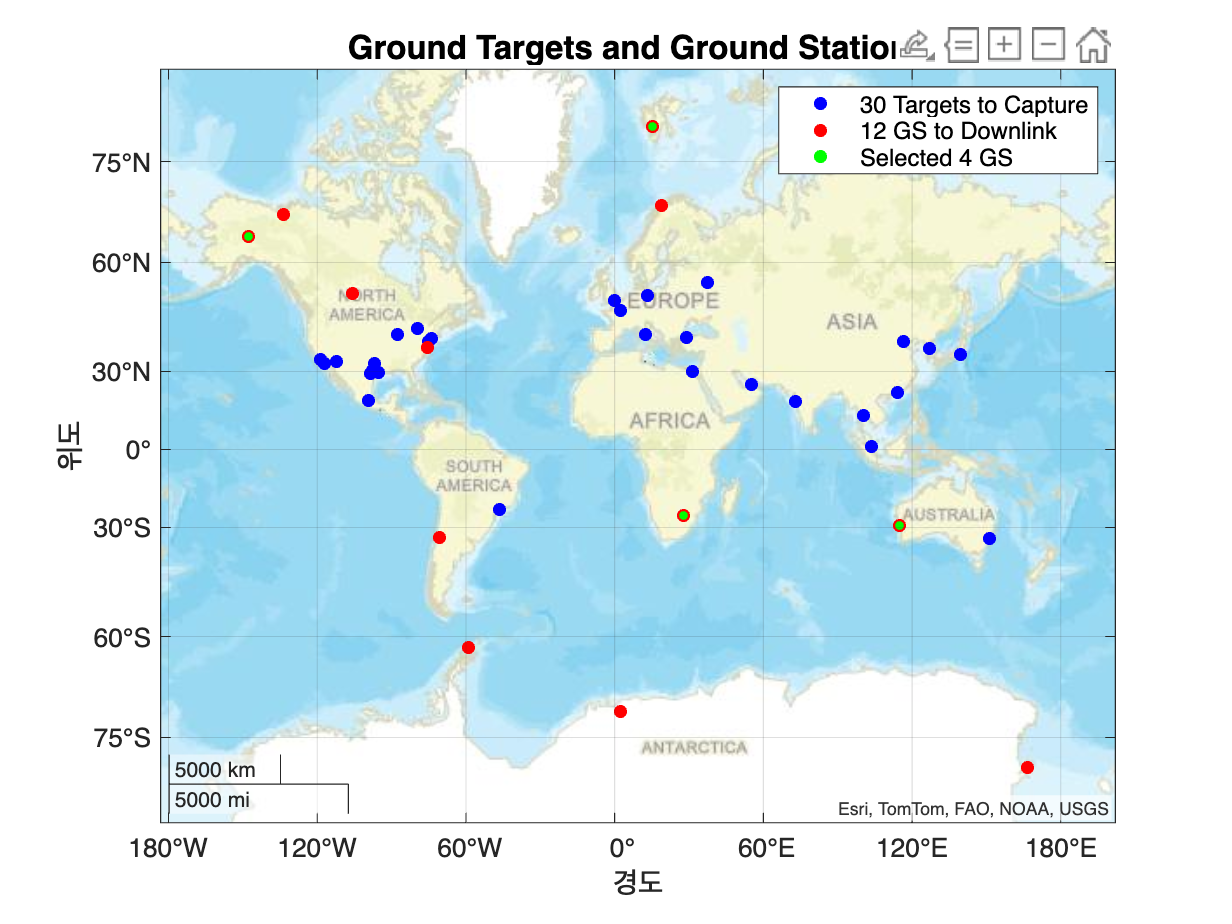


% Plot ground targets
geoscatter(g, ground_target(:,1), ground_target(:,2), 'b', 'filled');
% Plot ground stations
geoscatter(g, ground_station(:,1), ground_station(:,2), 'r', 'filled');
% Plot ground stations
geoscatter(g, ground_station_4GS(:,1), ground_station_4GS(:,2),15, 'green','filled');

legend('30 Targets to Capture','12 GS to Downlink','Selected 4 GS')

% Add labels and title
geobasemap(g, 'streets');
set(g, 'FontSize', 12);
title(g, 'Ground Targets and Ground Stations','FontSize',15,'FontWeight','bold');

hold(g, 'off');